# EGM and the political equilibrium

The current version is updated in ultimo January, 2023.

*Clean workspace, layout settings:*

clear;
clc;
close all;
base.layout();

## 1. Settings

 The main model components are collected in a few structs. To allow for more than one model instance (e.g. with different types of policies), we collect these in one layer here.

out = struct();

To initialize a model, we need to at least specify the relevant parameters that we want, what types of policies are in place (e.g. parameters of $\epsilon,\theta$), and what type of population data we might use. The following simply collects a number of default parameter values, and with the input 'E' uses empirical population data from "Inputdata.xlsx":

out.par = SolveF.setup('E'); % with input 'S'.

Add the epsilon/theta values:

out.par.epsilon = 0.513; out.par.theta = 0.815;

Before we calibrate the model, collect the targets:

target = SolveF.target();
%target.h = 0.68; % standard
target.h = 0.626; % new value
target.srate = 0.207 % update the savings rate

target = struct with fields:
           LSI: 0.5000
             r: 4.3000
         srate: 0.2070
    pensiontax: 0.2710
             h: 0.6260
            nu: 1.2169
        nu_row: 3
        nu_col: 1
            xi: 0.3500


target.pensiontax = 0.142; % 
out.par.epsilon = 0.560; % new value with pensiontax = 14.2
prefix = 'h0.626_tau.142'; % Add a prefix to all pdfs.
plot_polifyFunctions = 0; % if 1 it produces some figures that take a looong time.

The *SolveF *includes the following useful functions:

- *identify_policy(par): *Uses the EGM approach outlined in the paper to identify the period-specific policy functions. Returns a struct with fields *self.h, self.tau, self.tau_m. *This assums that the system is contributive $(\epsilon>0)$. 

- *sim_u(par): *Returns a path for labor supply, PEE taxes, and savings rates (*self.h, self.tau, self.srate *respectively) when pension type is universal $(\epsilon=0$).   

- *sim_c_unique(par): *returns a path for labor supply and PEE taxes (*self.h, self.tau, self.srate *respectively) when pension type is contributve $(\epsilon>0)$. 

- *cal_ss_c(par,target): *Calibrates the model using a steady state approximation; the steady state is approximated using a finite horizon EGM version with constant $\nu_t$. Assumes that $\epsilon>0$.

- *cal_dyn_c(par,target): *Dynamic calibration with the finite horizon EGM. Assumes that $\epsilon>0$

## 2. Baseline calibration and simulation

Our default approach is to use dynamic calibration, assuming the pension system is contributive (and expected to stay this way). This overwrites the existing parameter values with calibrated ones:

out.par = SolveF.cal_dyn_c(out.par,target);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

Given the calibrated parameter values, we simulate time path by defining the policy and simulating from it:

[out.sol, out.par] = SolveF.identify_policy(out.par);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

out.sim = SolveF.sim_c_unique(out.par,out.sol);
save('ArgentinaTargets.mat','target');
save('ArgentinaParameters.mat','out');

## 3. Counterfactuals:

NB: This way of accessing the solution is not used in the subsequent cells. When implemented, we can use this instead of manually testing each counterfactual. 

Collect solutions as function of epsilon and theta:

compare = containers.Map({'0,0'},{solveGivenPolicy(out.par, 0, 0);});
checkVals = [[1,1]; [0,1]; [1,0]; [0,0]; [0, out.par.theta]];
for i=1:size(checkVals,1)
    compare([num2str(checkVals(i,1)) ',' num2str(checkVals(i,2))]) = solveGivenPolicy(out.par,checkVals(i,1),checkVals(i,2));
end


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


Equation solved.

fsolve completed because the vector of function values is near zero
as 

### 3.1. What happens when $\epsilon=0$?

out_u = solveGivenPolicy(out.par, 0, out.par.theta);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



### 3.2. Taxes from contributive case, universal economic equilibrium?

TaxC_EEU = SolveF.sim_u_GivenTaxes(out_u.par,out.sim.tau);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



## 4. Results:

### "Table 2: Pension System reform, year 2010" 

obs2010 = 13; % which row number indicates 2010. 
table = NaN(2,3);
% Tax rates:
table(1,1) = out.sim.tau(obs2010); % initial
table(2,1) = out_u.sim.tau(obs2010); % universal
% savings rates (lag observation with -1 to get 2010 figures)
table(1,2) = out.sim.srate(obs2010-1); % initial
table(2,2) = out_u.sim.srate(obs2010-1); % universal
% labor supply:
table(1,3) = out.sim.h(obs2010); % initial 
table(2,3) = out_u.sim.h(obs2010); % universal

What are the relevant numbers in the case of universal pensions, but contributive tax rates?

table_taxC_EEU = [TaxC_EEU.tau(obs2010), TaxC_EEU.srate(obs2010-1), TaxC_EEU.h(obs2010)];

### 4.2. Plot paths

Define the main settings (colormaps, font sizes etc.):

psettings = figs.def_psettings(struct());
print = 1; % If 1 print to pdf, if 0 don't.
sim = out.sim; % baseline
sim_u = out_u.sim; % universal
sim_counterfactual = TaxC_EEU; % counterfactual

Print worker-to-retiree ratio:

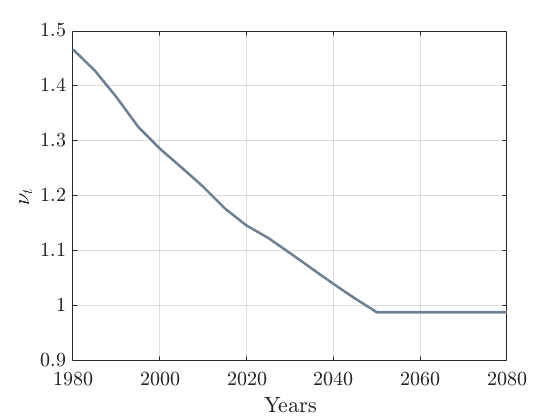

figs.w2r_ratio(out.par.dates,out.par,psettings,print,prefix);

Print tax policy for universal and contributive case:

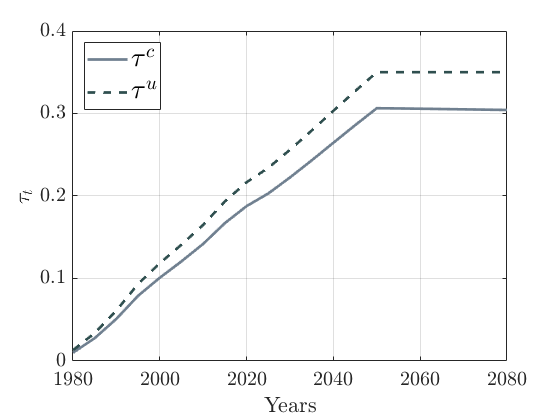

figs.comparetaxes(out.par.dates,psettings,sim,sim_u,print,prefix);

Print savings rates for universal, contributive, and counterfactual (tax = c, behavior = u):

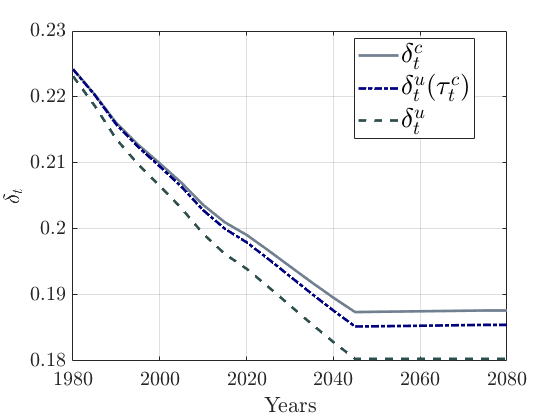

figs.comparesavings(out.par.dates,psettings,sim,sim_u,sim_counterfactual,print,prefix);

Print labor supply for universal, contributive, and counterfactual (tax = c, behavior = u):

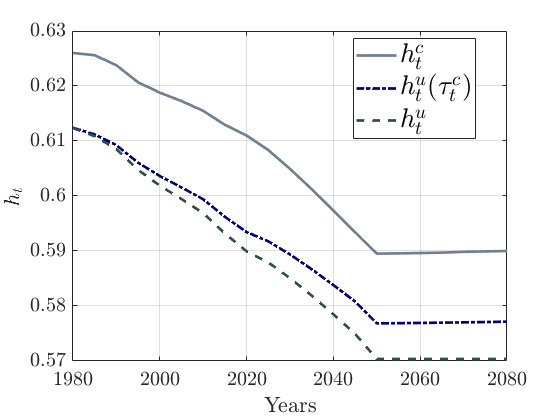

figs.comparelabor(out.par.dates,psettings,sim,sim_u,sim_counterfactual,print,prefix);

### 4.3: Plot the tax in 2010 as a function of epsilon, theta:

Define a grid of [epsilon, theta] values (drop pure universal case for simplicity; this takes a long time with large grids):

if plot_polifyFunctions == 1
   epsgrid = linspace(0.01,1,10);
   thetagrid = linspace(0,1,10); 
end

For each value on the grid, identify policy function and store h,tau,delta for 2010:

if plot_polifyFunctions == 1
   solgrid = struct();
    col = 13;
    [solgrid.tau, solgrid.h, solgrid.srate] = deal(NaN(length(epsgrid),length(thetagrid))); 
    par_ij = out.par;
    for i=1:length(epsgrid)
        par_ij.epsilon = epsgrid(i);
        for j=1:length(thetagrid)
            par_ij.theta = thetagrid(j);
            [temp_sol, temp_par] = SolveF.identify_policy(par_ij);
            temp_sim = SolveF.sim_c_unique(temp_par,temp_sol);
            solgrid.tau(i,j) = temp_sim.tau(col);
            solgrid.h(i,j) = temp_sim.h(col);
            solgrid.srate(i,j) = temp_sim.srate(col-1);
        end
    end 
end

Plots:

if plot_polifyFunctions == 1
    figs.SurfPlot(psettings,epsgrid,thetagrid,solgrid.tau,'tax',print,prefix);
    figs.SurfPlot(psettings,epsgrid,thetagrid,solgrid.h,'h',print,prefix);
    figs.SurfPlot(psettings,epsgrid,thetagrid,solgrid.srate,'srate',print,prefix);
end

function o = solveGivenPolicy(par, epsilon, theta)
    o = struct();
    o.par = par;
    o.par.epsilon = epsilon; o.par.theta = theta;
    if epsilon==0
        o.sim = SolveF.sim_u(o.par);
    else
        [o.sol, o.par] = SolveF.identify_policy(o.par);
        o.sim = SolveF.sim_c_unique(o.par,o.sol);
    end
end
function o = solveCounterFactual(par, epsilon, theta, taxes)
    par.epsilon = epsilon; par.theta = theta;
    if epsilon == 0
        o = SolveF.sim_u_GivenTaxes(par,taxes);
    else
        o = SolveF.sim_c_GivenTaxes(par,taxes);
    end
end